## Lab 5

#### 实验内容

- 使用Matlab录制、载入音频；

- 使用Matlab产生巴特沃斯滤波器；

- 使用Matlab函数计算频谱密度；

- 使用FIR滤波器产生语谱噪声；

- 使用FIR滤波器提取信号包络；

- 使用Matlab调整SNR；

- 使用Matlab标准化信号能量。

#### Part 1

要求：生成一段语谱噪声(speech-shaped noise (SSN))，并画出所使用的的语音信号及得到的语谱噪声的频谱。

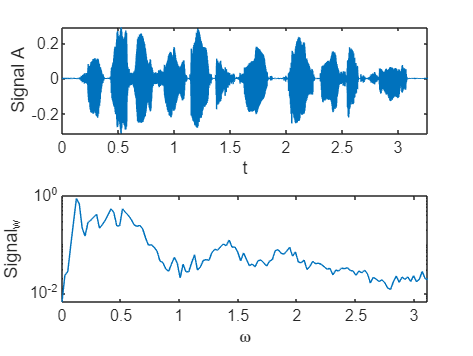

clear;
% Import files
[y_wav_a, fs_wav_a] = audioread("C_01_01.wav");
[y_wav_b, fs_wav_b] = audioread("C_01_02.wav");
y_wav_a = y_wav_a';
y_wav_b = y_wav_b';

nfft = 512;
noverlap = nfft / 2;
Windows = hamming(nfft);
% Returns the power spectral density
[Pxx,w] = pwelch(repmat(y_wav_a, 1, 10), Windows, noverlap, nfft, fs_wav_a);

% Generate filter
b = fir2(23330, w/(fs_wav_a / 2), sqrt(Pxx / max(Pxx)));

% Get spectrum
[h, hw] = freqz(b, 1, 128);

% Generate noise
N = length(y_wav_a);
noise = 1 - 2 * rand(1, N + length(b) - 1);

% Generate SSN
ssn = filter(b, 1, noise);
ssn = ssn(length(b) : end);

% Get spectrum
[hs, hws] = freqz(ssn, 1, 128);

% figure them
figure
subplot(2, 1, 1), plot(linspace(0, length(y_wav_a) / fs_wav_a, length(y_wav_a)), y_wav_a);
xlabel("t"), ylabel("Signal A"), xlim([0, length(y_wav_a) / fs_wav_a]);
subplot(2, 1, 2), semilogy(hw, abs(h));
xlabel("\omega"), ylabel("Signal_h_w"), xlim([hw(1), hw(end)]);

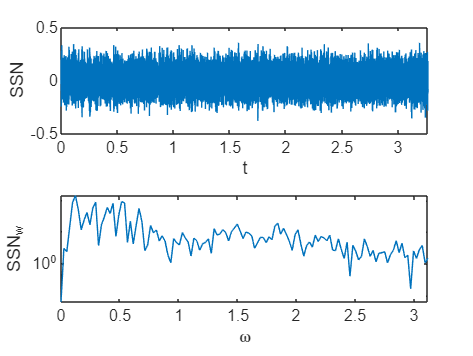


figure
subplot(2, 1, 1), plot(linspace(0, N / fs_wav_a, N), ssn);
xlabel("t"), ylabel("SSN"), xlim([0, N / fs_wav_a]);
subplot(2, 1, 2), semilogy(hws, abs(hs));
xlabel("\omega"), ylabel("SSN_h_w"), xlim([hws(1), hws(end)]);

#### Part 2

要求：在（1）中使用的语音信号里加入（1）中产生的语谱噪声SSN， 即令y = x + SSN，但需保证SNR为 -5 dB，并标准化y相对于x(t)的能量。

x = y_wav_a;

% Adjust the energy of SSN
ssn = ssn / norm(ssn) * norm(x) * 10 ^ (1 / 4);

% Test SNR
disp('The SNR is:')

The SNR is:


SNR = 20 * log10(norm(x) / norm(ssn))

SNR = -5


% Addition y with ssn
y = x + ssn;

% Normalize y to x
y = y / norm(y) * norm(x);

#### Part 3

要求：提取语音包络。

- 使用二阶巴特沃斯低通滤波器来获取包络， 其截止频率分别为fcut = 100、200和300Hz。在同一个图中绘制这三个包络波形，并描述它们之间的差异。

- 分别使用2阶和6阶巴特沃斯低通滤波器来获取包络， 截止频率为200Hz。在一个图中绘制这两个包络波形， 并描述它们之间的差异。 

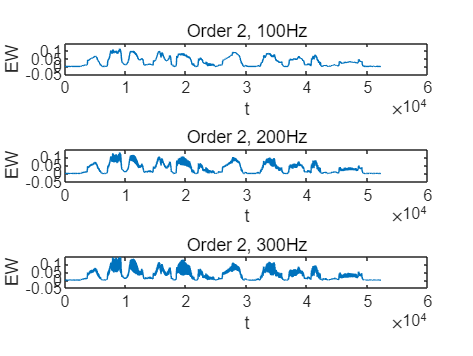

hfs = fs_wav_a / 2;

% Generate Butterworth Filters
[b1, a1] = butter(2, 100 / hfs, "low");
[b2, a2] = butter(2, 200 / hfs, "low");
[b3, a3] = butter(2, 300 / hfs, "low");
[b4, a4] = butter(6, 200 / hfs, "low");

x = abs(x);
y1 = filter(b1, a1, x);
y2 = filter(b2, a2, x);
y3 = filter(b3, a3, x);
y4 = filter(b4, a4, x);

% figure them
figure
subplot(3, 1, 1), plot(y1), xlabel("t"), ylabel("EW"), ylim([-0.05, 0.15]), title("Order 2, 100Hz");
subplot(3, 1, 2), plot(y2), xlabel("t"), ylabel("EW"), ylim([-0.05, 0.15]), title("Order 2, 200Hz");
subplot(3, 1, 3), plot(y3), xlabel("t"), ylabel("EW"), ylim([-0.05, 0.15]), title("Order 2, 300Hz");

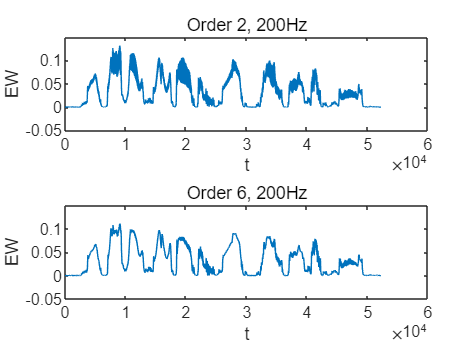


figure
subplot(2, 1, 1);
plot(y2), xlabel("t"), ylabel("EW"), ylim([-0.05, 0.15]), title("Order 2, 200Hz");
subplot(2, 1, 2);
plot(y4), xlabel("t"), ylabel("EW"), ylim([-0.05, 0.15]), title("Order 6, 200Hz");

分析：

- 使用二阶巴特沃斯低通滤波器来获取包络，其它条件不变时，随着滤波器截止频率的增大，滤波器提取包络的能力逐渐变差，包络中高频成分增加，在信号值高峰处显示出较不整齐的特点。

- 使用截止频率固定为200Hz的巴特沃斯低通滤波器来获取包络，六阶滤波器的提取效果明显好于二阶滤波器，信号高频成分比较之下明显减少，说明在其它条件不变时，滤波器阶数越高，滤波效果越好。

#### Part 4

要求：音频录制。

% Record voice 1
recObj_1 = audiorecorder(11025,8,1);
disp('Start speaking.')

Start speaking.


recordblocking(recObj_1,5);
disp('End of Recording.');
% Play back the recording
play(recObj_1);
% Store data in double-precision array
myRecording_1 = getaudiodata(recObj_1);
% Plot the waveform
plot(myRecording_1); 
% audiowrite(wav_1,myRecording_1,11025);

% Record voice 2
recObj_2 = audiorecorder(11025,8,1);
disp('Start speaking.')
recordblocking(recObj_2,5);
disp('End of Recording.');
% Play back the recording
play(recObj_2);
% Store data in double-precision array
myRecording_2 = getaudiodata(recObj_2);
% Plot the waveform
plot(myRecording_2); 
% audiowrite(wav_2,myRecording_2,11025);